%% ========== 合并图：热浪期 + 非热浪期 + 四季差异（含显著性稀疏打点）==========
fprintf('生成合并图（热浪期、非热浪期、四季差异，带显著性标记）...\n');

生成合并图（热浪期、非热浪期、四季差异，带显著性标记）...


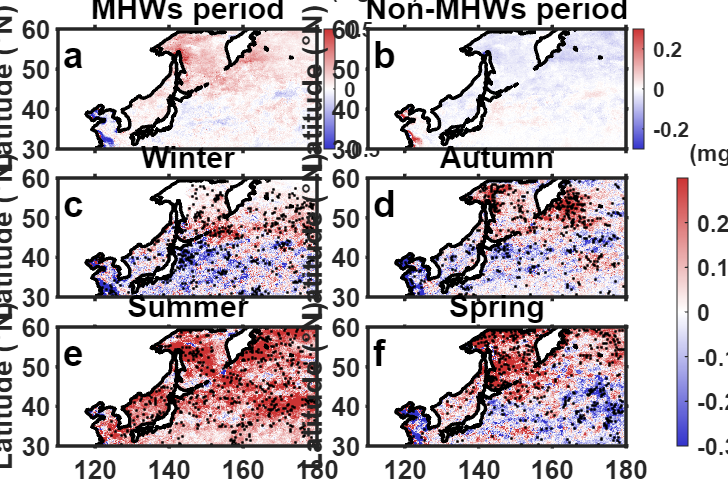


% 加载相关性数据（若尚未加载）
if ~exist('seasonal_p_value', 'var')
    corr_file = fullfile(output_dir, 'correlation_analysis_data.mat');
    if exist(corr_file, 'file')
        C = load(corr_file);
        seasonal_p_value = C.correlation_data.seasonal_p_value;   % [4, nlon, nlat]
    else
        warning('未找到相关性数据文件，显著性打点将被跳过。');
        seasonal_p_value = nan(4, n_lon_chl, n_lat_chl);
    end
end

% 显著性打点参数
p_threshold = 0.05;
max_points = 500;          % 每个季节子图最多显示的点数
marker_size = 3;
marker_color = [0, 0, 0];

fig_combined = figure('Position', [100, 100, 1500, 1000], 'Color', 'white');

% 子图位置参数（间距适中）
left_margin   = 0.08;
right_margin  = 0.14;
bottom_margin = 0.08;
top_margin    = 0.06;
h_gap = 0.07;
v_gap = 0.06;

total_width  = 1 - left_margin - right_margin;
total_height = 1 - bottom_margin - top_margin;
sub_w = (total_width - h_gap) / 2;
sub_h = (total_height - 2*v_gap) / 3;

pos = {
    [left_margin, bottom_margin+2*(sub_h+v_gap), sub_w, sub_h];   % a
    [left_margin+sub_w+h_gap, bottom_margin+2*(sub_h+v_gap), sub_w, sub_h]; % b
    [left_margin, bottom_margin+1*(sub_h+v_gap), sub_w, sub_h];   % c
    [left_margin+sub_w+h_gap, bottom_margin+1*(sub_h+v_gap), sub_w, sub_h]; % d
    [left_margin, bottom_margin+0*(sub_h+v_gap), sub_w, sub_h];   % e
    [left_margin+sub_w+h_gap, bottom_margin+0*(sub_h+v_gap), sub_w, sub_h]  % f
};

data_cell = {mean_hw_anom, mean_non_hw_anom, ...
             squeeze(season_diff_anom(1,:,:)), squeeze(season_diff_anom(4,:,:)), ...
             squeeze(season_diff_anom(3,:,:)), squeeze(season_diff_anom(2,:,:))};
titles = {'MHWs period', 'Non-MHWs period', ...
          'Winter', 'Autumn', 'Summer', 'Spring'};
caxis_vals = {[-0.5, 0.5], [-0.3, 0.3], [-0.3, 0.3], [-0.3, 0.3], [-0.3, 0.3], [-0.3, 0.3]};

% 季节索引对应关系（data_cell中的位置 3:6 对应季节 1,4,3,2）
season_idx_map = [1, 4, 3, 2];  % Winter, Autumn, Summer, Spring

for i = 1:6
    ax = axes('Position', pos{i});
    imagesc(target_lon_chl, target_lat_chl, data_cell{i}');
    set(gca, 'YDir', 'normal', 'TickDir', 'out', 'Box', 'on', 'LineWidth', 1.5);
    axis tight;
    if ~isempty(coast_lon) && ~isempty(coast_lat)
        hold on; plot(coast_lon, coast_lat, 'k', 'LineWidth', 1.5); hold off;
    end
    colormap(ax, custom_cmap1);
    caxis(caxis_vals{i});
    if i == 5 || i == 6
        xlabel('Longitude (°E)', 'FontSize', 12, 'FontWeight', 'bold');
    else
        set(gca, 'XTickLabel', []);
    end
    ylabel('Latitude (°N)', 'FontSize', 12, 'FontWeight', 'bold');
    set(gca, 'FontSize', 11, 'FontWeight', 'bold');
    xlim([min(target_lon_chl), max(target_lon_chl)]);
    ylim([min(target_lat_chl), max(target_lat_chl)]);
    text(0.02, 0.98, char('a'+i-1), 'Units', 'normalized', ...
         'FontSize', 16, 'FontWeight', 'bold', 'VerticalAlignment', 'top');
    title(titles{i}, 'FontSize', 13, 'FontWeight', 'bold');
    
    % ----- 显著性打点（仅针对后四个季节子图）-----
    if i >= 3
        hold on;
        season_id = season_idx_map(i-2);      % 当前子图对应的季节编号
        p_map = squeeze(seasonal_p_value(season_id, :, :))';
        sig_mask = (p_map < p_threshold) & ~isnan(p_map);
        [sy, sx] = find(sig_mask);
        if ~isempty(sx)
            if length(sx) > max_points
                rng(0);   % 可重复随机抽样
                idx = randperm(length(sx), max_points);
            else
                idx = 1:length(sx);
            end
            plot(target_lon_chl(sx(idx)), target_lat_chl(sy(idx)), '.', ...
                'MarkerSize', marker_size, 'Color', marker_color);
        end
        hold off;
    end
    
    % 前两个子图的独立色标（水平单位）
    if i == 1 || i == 2
        ax_pos = get(ax, 'Position');
        cb = colorbar('Position', [ax_pos(1)+ax_pos(3)+0.01, ax_pos(2), 0.015, ax_pos(4)]);
        cb.Label.String = '(mg m^{-3})';
        cb.Label.FontSize = 10;
        cb.Label.FontWeight = 'bold';
        cb.Label.Rotation = 0;
        drawnow;
        cb.Label.VerticalAlignment = 'middle';
        cb.Label.HorizontalAlignment = 'left';
        cb_pos = get(cb, 'Position');
        set(cb.Label, 'Position', [cb_pos(1)+cb_pos(3)+0.005, cb_pos(2)+cb_pos(4)/2, 0]);
        cb.FontSize = 9;
        cb.FontWeight = 'bold';
    end
end

% 公共色标（水平单位）
pos_c = pos{3}; pos_d = pos{4}; pos_e = pos{5}; pos_f = pos{6};
y_bottom = min([pos_c(2), pos_d(2), pos_e(2), pos_f(2)]);
y_top    = max([pos_c(2)+pos_c(4), pos_d(2)+pos_d(4), pos_e(2)+pos_e(4), pos_f(2)+pos_f(4)]);
cb_common = colorbar('Position', [0.93, y_bottom, 0.015, y_top - y_bottom]);
cb_common.Label.String = '(mg m^{-3})';
cb_common.Label.FontSize = 11;
cb_common.Label.FontWeight = 'bold';
cb_common.Label.Rotation = 0;
drawnow;
cb_common.Label.VerticalAlignment = 'middle';
cb_common.Label.HorizontalAlignment = 'left';
cb_pos = get(cb_common, 'Position');
set(cb_common.Label, 'Position', [cb_pos(1)+cb_pos(3)+0.005, cb_pos(2)+cb_pos(4)/2, 0]);
cb_common.FontSize = 10;
cb_common.FontWeight = 'bold';


% 保存（可选）
% saveas(fig_combined, fullfile(output_dir, 'combined_six_panels_with_sig.png'));